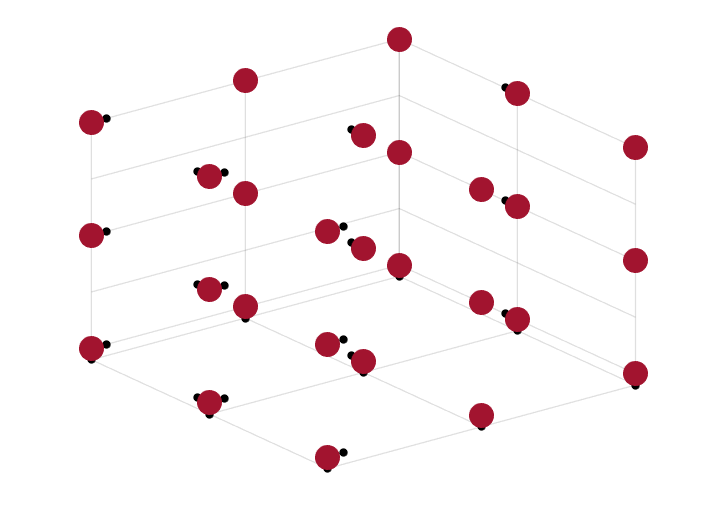

full = fullfact([3,3,3]);
orthogonal = [1 1 1;
              1 2 3;
              1 3 2;
              2 1 3;
              2 2 2;
              2 3 1;
              1 1 2;
              1 2 1;
              2 3 3];
uniform = [1,3,5;
           2,5,2;
           3,2,4;
           4,4,1;
           5,1,3];

figure('Name','Full');
scatter3(full(:,1), full(:,2), full(:,3), 100, 'filled', 'MarkerFaceColor', [0.6350 0.0780 0.1840]);
hold on;

% plot3(full(:,1), full(:,2), ones(size(full,1),1)*0.9, 'k.', 'MarkerSize', 10); % XY平面投影
% plot3(full(:,1), ones(size(full,1),1)*2+0.1, full(:,3), 'k.', 'MarkerSize', 10); % XZ平面投影
% plot3(ones(size(full,1),1)*1+0.1, full(:,2), full(:,3), 'k.', 'MarkerSize', 10); % YZ平面投影

ax = gca;
ax.XAxis.Visible = 'off';
ax.YAxis.Visible = 'off';
ax.ZAxis.Visible = 'off';

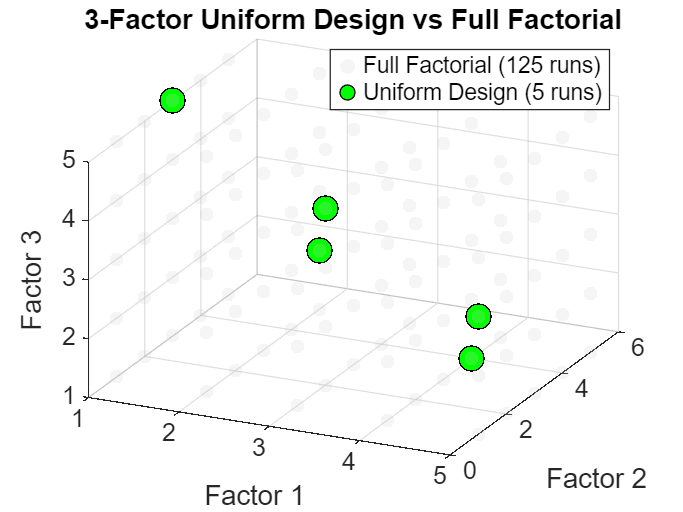

% 使用U5(5^3)均匀表示例
uniform_points = [1,3,5; 2,5,2; 3,2,4; 4,4,1; 5,1,3];
levels = 5; % 各因素水平数
[X1,X2,X3] = ndgrid(1:levels, 1:levels, 1:levels);
points = [X1(:), X2(:), X3(:)]; % 生成125个全因子点
figure;
% 绘制全因子点（半透明）

figure;
scatter3(points(:,1), points(:,2), points(:,3),  30, [0.8 0.8 0.8], 'filled', 'MarkerFaceAlpha',0.2);
hold on;

% 绘制所有点

% % X方向连线
% for y = 1:levels
%     for z = 1:levels
%         idx = (X2(:)==y) & (X3(:)==z);
%         plot3(X1(idx), X2(idx), X3(idx), 'k-', 'LineWidth',0.5);
%     end
% end
% 
% % Y方向连线
% for x = 1:levels
%     for z = 1:levels
%         idx = (X1(:)==x) & (X3(:)==z);
%         plot3(X1(idx), X2(idx), X3(idx), 'k-', 'LineWidth',0.5);
%     end
% end
% 
% % Z方向连线
% for x = 1:levels
%     for y = 1:levels
%         idx = (X1(:)==x) & (X2(:)==y);
%         plot3(X1(idx), X2(idx), X3(idx), 'k-', 'LineWidth',0.5);
%     end
% end
% 
% view(3); axis tight;
% xlabel('Factor1'); ylabel('Factor2'); zlabel('Factor3');


hold on;

% 绘制均匀设计点（突出显示）
scatter3(uniform_points(:,1), uniform_points(:,2), uniform_points(:,3),...
    100, 'g', 'filled', 'MarkerEdgeColor','k');

% 标注与美化
xlabel('Factor 1'); ylabel('Factor 2'); zlabel('Factor 3');
title('3-Factor Uniform Design vs Full Factorial');
legend({'Full Factorial (125 runs)', 'Uniform Design (5 runs)'}, 'Location','best');
view(25, 30); % 调整视角
grid on;

% 使用U6(6^3)均匀设计表
UD = [1,3,5; 2,6,2; 3,2,6; 4,5,1; 5,1,4; 6,4,3];
X = UD(:,1:2); % 前两列作为输入因子
y = UD(:,3);   % 第三列作为响应值

% 创建二次项特征
X_reg = [ones(size(X,1),1), X, X.^2, X(:,1).*X(:,2)];
beta = regress(y, X_reg); % 回归系数

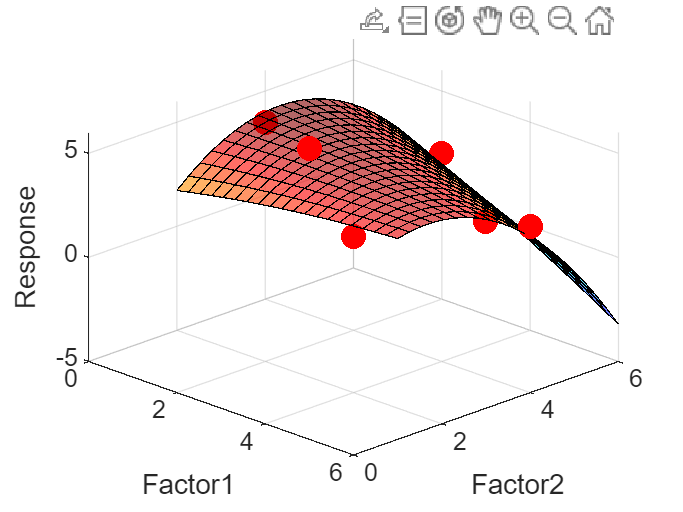


% 创建网格数据
[x1_grid,x2_grid] = meshgrid(linspace(1,6,20), linspace(1,6,20));

% 预测响应值
y_pred = beta(1) + beta(2)*x1_grid + beta(3)*x2_grid +...
         beta(4)*x1_grid.^2 + beta(5)*x2_grid.^2 + beta(6)*x1_grid.*x2_grid;

figure;
surf(x1_grid, x2_grid, y_pred, 'FaceAlpha',0.6); % 半透明曲面
colormap(jet); hold on;
scatter3(X(:,1), X(:,2), y, 100, 'r', 'filled'); % 设计点投影
view(45,30); 
xlabel('Factor1'); ylabel('Factor2'); zlabel('Response');


% 计算曲面点间距
[~,D] = knnsearch([x1_grid(:),x2_grid(:),y_pred(:)], [X,y]);
disp(['平均邻距：', num2str(mean(D))]);

平均邻距：0.4857


% 生成6个示例点（需替换为实际数据）
points = [1 3 5; 2 6 2; 3 2 6; 4 5 1; 5 1 4; 6 4 3];

% 构建二次响应曲面模型
X = points(:,1:2); 
y = points(:,3);
designMat = [ones(6,1), X, X.^2, X(:,1).*X(:,2)];
beta = regress(y, designMat);

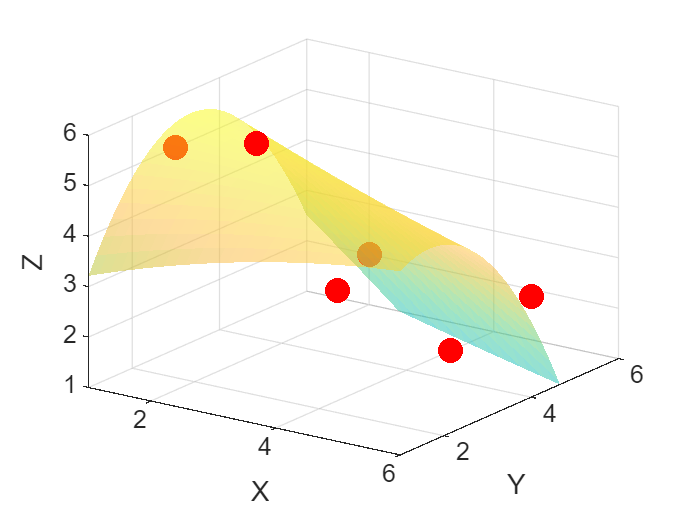


% 生成6x6x6空间网格
[xx,yy] = meshgrid(linspace(1,6,30), linspace(1,6,30));
zz = beta(1) + beta(2)*xx + beta(3)*yy +...
     beta(4)*xx.^2 + beta(5)*yy.^2 + beta(6)*xx.*yy;

% 可视化
figure
surf(xx, yy, zz, 'FaceAlpha',0.5, 'EdgeColor','none');
hold on
scatter3(points(:,1), points(:,2), points(:,3), 100, 'r', 'filled');
axis([1 6 1 6 1 6]); 
xlabel('X'); ylabel('Y'); zlabel('Z');
view(35,25);

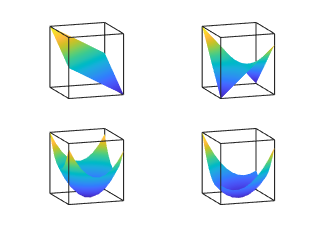

% 生成示例数据
X = linspace(-10,10,10);
Y = linspace(-10,10,10);
[XX,YY] = meshgrid(X,Y);

figure;
tiledlayout(2,2,'TileSpacing','compact');

nexttile;
Z1 = XX + YY;
surf(X,Y,Z1,'EdgeColor','none','FaceColor','interp');
view([611 11])
set(gca,'Box','on','BoxStyle','full');
ax = gca;
ax.XAxis.Visible = 'off';
ax.YAxis.Visible = 'off';
ax.ZAxis.Visible = 'off';
grid off;

% xlabel('x');ylabel('y');zlabel('z');

Z2 = XX.*YY + XX + YY;
nexttile;
surf(X,Y,Z2,'EdgeColor','none','FaceColor','interp');
view([611 11])
set(gca,'Box','on','BoxStyle','full');
ax = gca;
ax.XAxis.Visible = 'off';
ax.YAxis.Visible = 'off';
ax.ZAxis.Visible = 'off';
grid off;

Z3 = XX.^2 + YY.^2 + XX + YY;
nexttile;
surf(X,Y,Z3,'EdgeColor','none','FaceColor','interp');
view([611 11])
set(gca,'Box','on','BoxStyle','full');
ax = gca;
ax.XAxis.Visible = 'off';
ax.YAxis.Visible = 'off';
ax.ZAxis.Visible = 'off';
grid off;

Z4 = XX.^2 + YY.^2 + XX.*YY + XX + YY;
nexttile;
surf(X,Y,Z4,'EdgeColor','none','FaceColor','interp');
view([611 11])
set(gca,'Box','on','BoxStyle','full');
ax = gca;
ax.XAxis.Visible = 'off';
ax.YAxis.Visible = 'off';
ax.ZAxis.Visible = 'off';
grid off;

% 共面点测试
pts1 = [1,3,5; 2,5,2; 3,2,4; 4,4,1; 5,1,3];
disp(check_coplanar(pts1))

   1




function isCoplanar = check_coplanar(points)
    % 输入：5x3矩阵，每行代表一个三维点坐标
    % 输出：true表示共面，false表示不共面
    
    base_point = points(1,:);
    vectors = points(2:end,:) - base_point;  % 生成相对向量
    A = vectors';                            % 转置为3x4矩阵
    tol = max(size(A)) * eps(norm(A));       % 计算合理容差
    rank_val = rank(A, tol);                 % 带容差的矩阵秩计算
    isCoplanar = (rank_val < 3);             % 判断秩是否小于3
end